# Boas práticas


clear all;
close all;
clc;


## Importando os dados


Leitura         %%% Importa os dados de entrada

T = 1e-3        %%% tempo de amostragem

T = 1.0000e-03

N = length(In)  %%% Número de amostras     

N = 4685

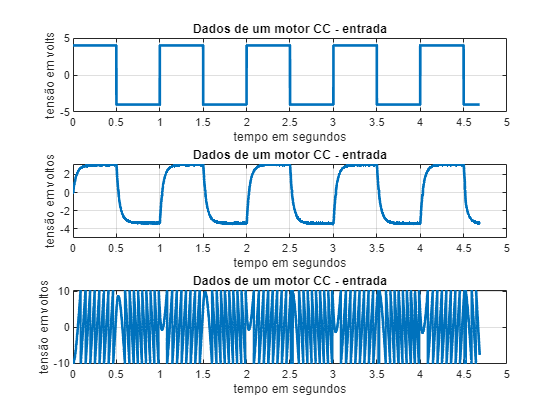


%%% Criando a variável tempo

tempo = linspace(0,N*T,N);

% Verificando os dados

subplot(3,1,1)

plot(tempo,In,"LineWidth",2)
title("Dados de um motor CC - entrada")
xlabel("tempo em segundos")
ylabel("tensão em volts")
grid

subplot(3,1,2)

plot(tempo,Vel,"LineWidth",2)
title("Dados de um motor CC - entrada")
xlabel("tempo em segundos")
ylabel("tensão em voltos")
grid

subplot(3,1,3)

plot(tempo,Pos,"LineWidth",2)
title("Dados de um motor CC - entrada")
xlabel("tempo em segundos")
ylabel("tensão em voltos")
grid

## Estimando Laplace


%%% Um modelo de primeira ordem que relacione a entrada coma velocidade

Km = 20; %%% valor inicial do ganho
pm = 10;

Gp = tf(Km,[1 pm])  % Função de transferência

Gp =
 
    20
  ------
  s + 10
 
Continuous-time transfer function.



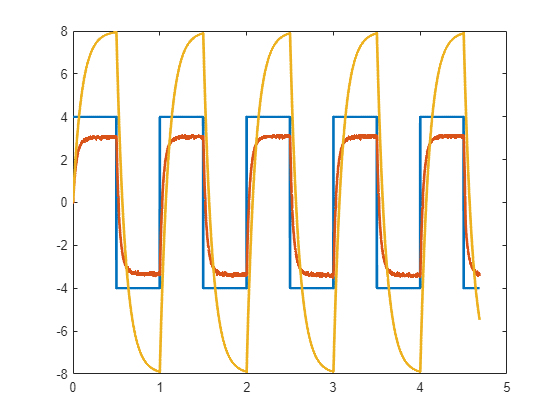

y = lsim(Gp,In,tempo);  %%% Aplico no modelo a mesma entrada que apliquei no sistema real

% Visualizando modelo
figure(2)
plot(tempo,In,tempo,Vel,tempo,y,"LineWidth",2);

## Ajustando o modelo com dados

x0 = [1 1]

x0 =      1     1


X = fminsearch(@(x) ErroQuadratico(x,Vel,tempo,In),x0)

X =    22.4732   28.0882


Km = X(1)

Km = 22.4732

Pm = X(2)

Pm = 28.0882


Gp = tf(Km,[1 Pm])

Gp =
 
    22.47
  ---------
  s + 28.09
 
Continuous-time transfer function.



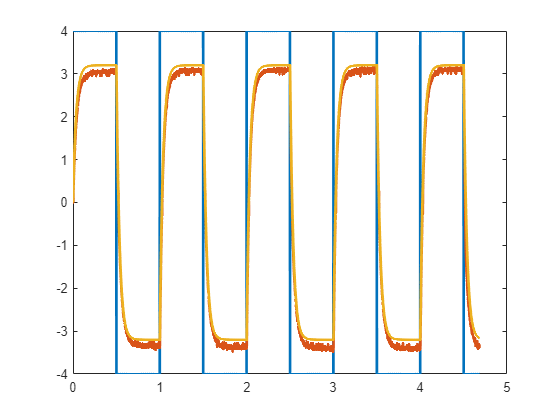

y = lsim(Gp,In,tempo);

figure(3);
plot(tempo,In,tempo,Vel,tempo,y,"LineWidth",2);